# Laboratory 2: Graziani, Di Via, Hiller-Szala

## Introduction 

**Mastermind** is a classic code-breaking game that challenges players to use logic to discover a hidden sequence of colours (target combination). The secret code is fixed, and the player must guess this code within a limited number of attempts, receiving feedback about correct colours in right positions and correct colours in the wrong positions.

This problem can be effectively solved using **genetic algorithms**, which mimic natural selection to iteratively evolve better guesses toward the correct solution.

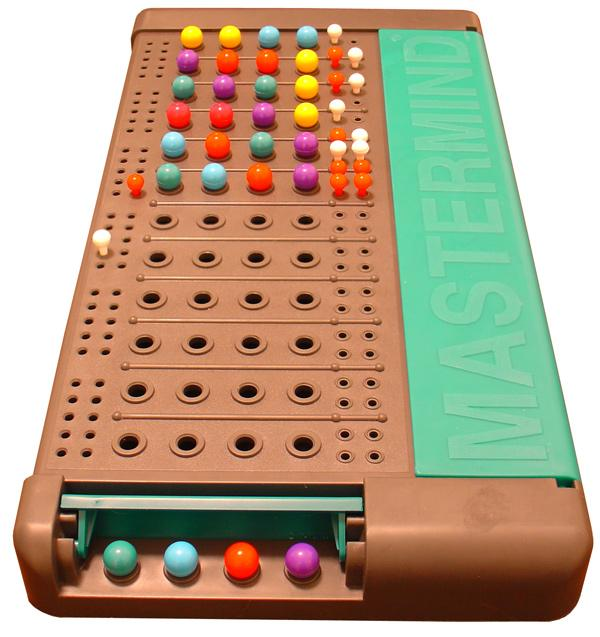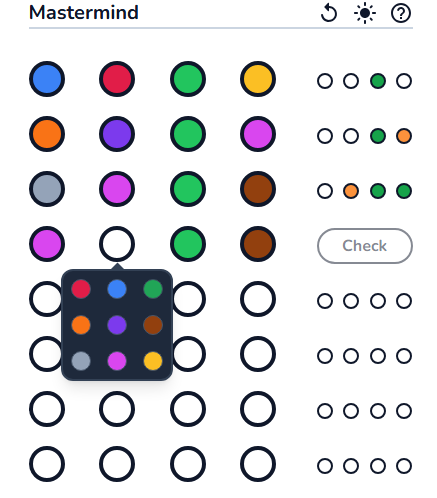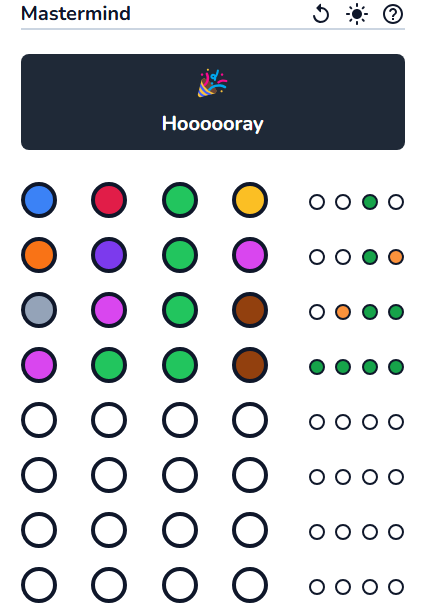

## Mathematical Background

A genetic algorithm is a biology inspired technique designed to solve specific problems by simulating the survivability of a population in a given environment. In a mathematical context, the **environment**  represents the problem itself and the **population** $\mathcal{P}=\{ x_1, \cdots, x_P \}$ made up of $P$ **individuals** represents a set of particular solutions to it. The goal is to **maximize** a **fitness function**, which evaluates the ability of each individual to "survive"  i.e. to effectively address the problem.

The initialization of this algorithm begins by defining the **genetic code (genotype)** of each of the $P$ individuals in the population as a string of $N_b$ **symbols** (called **genes**) belonging to a given **alphabet**. Once the initial population is defined, the evolutionary process is the following:

## ***Parents selection***

Two individuals are selected to reproduct and become parents of a new offspring depending on the evaluation of the **fitness function** $f$ for each individual $\{x_i\}_{i=1}^P \in \mathcal{P}$. The most common criterion are the **proportional to fitness selection, tournament selection **and** rank selection**. 

## ***Crossover Reproduction ***

Given the two parents and a **probability of crossover **$P_c$, reproduction occurs if a random number drawn from a uniform distribution $r \in \mathcal{U}([0,1])$ is less than the crossover probability $P_c$. If reproduction is successful, a **crossover operator** combines the genetic code of the two parents to produce offspring, according to specific techniques. The most common crossover techniques are the **one point crossover, **the** two points crossover **and the** uniform crossover. **

If reproduction doesn't occur, a new couple of parents is selected or the children are generated as just clones of the parents.

## *Mutation*

In the children generation stage, a **mutation operator** is also applied. Similarly, given a very low **probability of mutation** $P_m$, mutation on a gene occurs if a random number drawn in the uniform distribution $r \in \mathcal{U}([0,1])$ is less than the probability of mutation $P_m$ for each of the $N_b$ genes. On the contrary, if $r>P_m$ mutation is not performed on the gene.

## *Natural Selection*

 Eventually, the **natural selection** stage allows just the best $P$ individuals of the whole population to survive. Different criterions can be used to select the best $P$ individuals:

- selecting $P$ individuals from just the offspring $P_\text{new}$;

- selecting $P$ individuals from the whole population $P+P_\text{new}$;

- selecting the single best individual from the whole population $P+P_\text{new}$ and $P-1$ individuals from the offspring $P_\text{new}$.

The generation cycle is then repeated on the population made of $P$ individual chosen, until a stop criterion is satisfied. A common **stop criterion** used is $|\bar{f}^{(t)}-\bar{f}^{(t-1)}| < \epsilon$ where $\epsilon$ is a fixed threshold and $\bar{f}^{(t)}$ is the average fitness computed at iteration $t$ as

$\bar{f}^{(t)}=\frac{\sum_{i=1}^P f(x_i^{(t)})}{P} \quad \text{with } x_i^{(t)} \in \mathcal{P}^{(t)}$ .

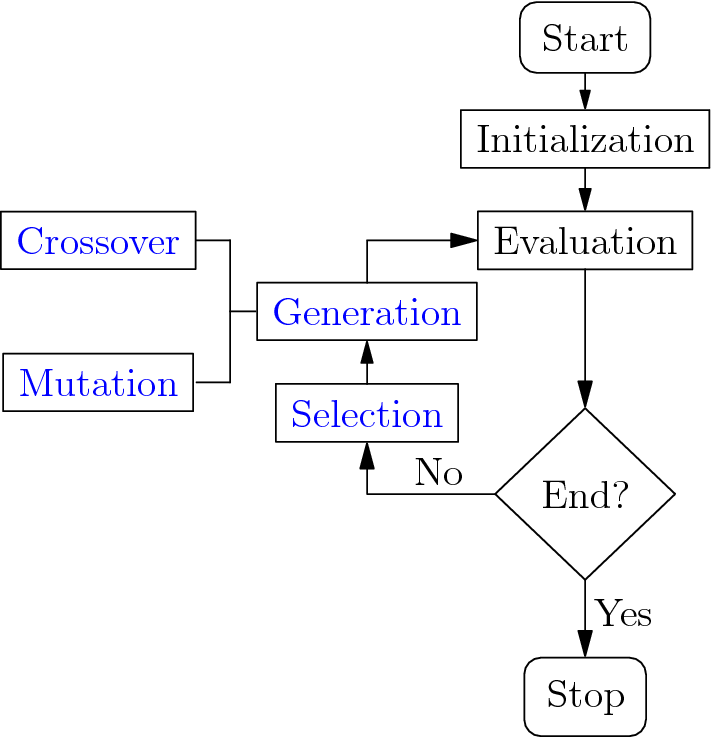

## Laboratory Introduction

The goal of this laboratory is to implement a genetic algorithm that determines the secret combination of Master Mind. We consider the sequences to be made up of $N_b=6$ colours. The alphabet considered is made of six possible colours (**G**reen, **R**ed, **Y**ellow, **W**hite, **B**lack, **P**ink), which are decoded in terms of number from 1 to 6, and repetitions are allowed. 

## *Initialization*

We consider a population of 10 individuals, initially generated as strings made up of random values from 1 to 6, and a fitness function depending on the number of right colours in right position and right colours in wrong position:

$f_i^{(t)}= w_1 \cdot  N_{CGPG} + w_2 \cdot  N_{CGPS}$.

In this laboratory we assign a score of $w_1=+2$ for each correct color in the correct position and $w_2=+1$ for each correct color in the wrong position. We notice that the maximum fitness value reachable is $f_\max= w_1 \cdot N_b$, which is equal to 12 in our case. 

For each generation we consider a number of descendants equal to 20 individuals, by having two children per couple. 

## *Parents Selection, Crossover Reproduction and Mutation*

The parents are selected using the **tournament selection criterion**: a random permutation is performed on the individuals in the population and just the first T individuals, with $2 < T << P$, are selected for the competition. In this report the two individuals with the highest fitness among the $T$=4 individuals chosen will be the parents selected for reproduction.

 Given a  probability of crossover $P_c=0.9$, all of the three different crossover operators mentioned previously are implemented:

- **One-point crossover **consists of picking up a random point in between $1$ and $N_{b}-1$ to decide in which position we split the parents' genotypes. The first descendant will be generated by considering the first part of his genotype as the first part of the genotype of the first parent, and the second part of his genotype (after the crossover point) as the second part of the genotype of the second parent. Similarly, the second descendant will be generated considering the first part of the genotype of the second parent followed by the second part of the genotype of the first parent. 

- In **two-point crossover**, two random crossover points are selected as in the one point crossover. The first descendant will be generated considering the first and third part of his code from the first parent, while the second part of this code (the one between the two crossover points) from the second parent. Analogously, the second descendant will be generated by considering the first and third part of his code from the second parent, while the second part of this code from the first parent. 

- In **uniform crossover**, each gene of the offspring is selected independently by randomly choosing one of the two parents with equal probability (50%). This process is repeated for every gene position to create the two descendants, $N_b$ times.

If crossover is not performed, the children are considered to be clones of the parents.

Mutation operator is applied by considering a probability of mutation $P_m=\frac{1}{N_b}=\frac{1}{6}$.

## *Natural Selection and Stop Criterion*

As natural selection criterion we decide to consider the best $P$ individuals from just the offspring $P_\text{new}$ and we stop the generation cycle when the maximum level of fitness is found in the population ($f_\max=12$) or when the maximum number of iterations is reached (max_count=500). 

In this way, the secret combination is generated randomly each time the code is run and is eventually guessed after a certain number of iterations. To visualize the behaviour of the fitness function we realized a plot showing how the average fitness of the population and the fitness of the best individual change as the generations (iterations) increase.

clear;clc;close all;

## Step 0: Initialization

%-------------------------------------------------------------------------------------------------------
%--------------------------------------------------PROBLEM SETTING--------------------------------------
%-------------------------------------------------------------------------------------------------------

%rng(42); %fixing a seed for reproducibility
Nb=6; %Defining the length of the sequence

%------------ALPHABET CHOOSING--------------------------------
alphabet = 1:6; %Defining the alphabet used for the sequence

%Examples of possible different alphabets working with the generalization
%(uncomment the lines):

%Fully numerical alphabet
%alphabet= [1,3,12,30] ;

%Fully character alphabet
%alphabet=['G', 'R', 'Y', 'W', 'B', 'P']; %It works!

%Mixed alphabet
%alphabet=['A', 'B', 'C', 'D', 0, 1]; %Everything ok except of the printings

%---------------TARGET, TEST AND GENERALIZATION-------------------------------
%Defining target combination to guess
target=randi([1,6], 1, Nb)

target =      4     6     6     1     3     3



% %Generalization of target combination generation for each kind of alphabet
% random_indices = randi(length(alphabet), 1, Nb);
% target = alphabet(random_indices)


%Defining the population - test combination
P=10; %number of individuals in population
%P must be at least 4 in order to make the our tournment selection work

%Randomly generating the P individuals in a matrix P x Nb
test=randi([1,6], P, Nb)

test =      6     3     3     2     2     5
     5     1     5     1     2     2
     2     6     1     2     5     6
     1     3     1     1     4     6
     1     2     4     3     1     6
     2     6     5     6     3     5
     4     6     1     6     5     2
     5     1     1     3     1     4
     3     1     1     3     1     5
     5     4     3     5     6     2



%Generalization of target combination generation for each kind of alphabet
% random_indices = randi(numel(alphabet), P, Nb);
% test = alphabet(random_indices)


## Step I: Genetic Algorithm

Implementing the genetic algorithm described in the theoretical section.

%-------------------------------------------------------------------------------------------------------
%---------------------------------------------INITIALIZATION--------------------------------------------
%-------------------------------------------------------------------------------------------------------
Pc=0.9; %Probability of crossover
Pm=1/Nb; %Probability of mutation

%Defining the fitness function for the problem
w1=2; %Weighting right colours in true position
w2=1; %Weighting the right colours in wrong position
fitness=@(Ncgpg,Ncgps) w1*Ncgpg+w2*Ncgps;


count=0; max_count=500; %Counter for the while-stop criterion
average_fitness=zeros(1,max_count); %average fitness of the population for each iteration
best_fitness=zeros(1,max_count); %maximum fitness in the population for each iteration

%Initializing the fitness on the test
[~, ~, fitness_individuals]=evaluate_fitness(test, target, alphabet, fitness);
%Initializing the descendants matrix 2P x Nb
%We consider each couple of parents to generate 2 children
descendants=zeros(2*P , Nb);

%-------------------------------------------------------------------------------------------------------
%---------------------------------------------GENETIC ALGORITHM-----------------------------------------
%-------------------------------------------------------------------------------------------------------

while max(fitness_individuals)<12 && count<max_count

    %------------------------NATURAL SELECTION-------------------------
    %Selecting just the best P individuals
    [~, idx] = maxk(fitness_individuals, P);
    test = test(idx, :);
    fitness_individuals=fitness_individuals(idx);

    %---------------------------REPRODUCTION---------------------------
    for i=1:P
        %Tournament parent selection
        [parent1, parent2]=tournament_selection(test, fitness_individuals, 4);

        %Crossover and mutation
        [child1, child2]=crossover(parent1, parent2, alphabet, Pc, 1); %one point crossover
        %[child1, child2]=crossover(parent1, parent2, alphabet, Pc, 2); %two points crossover
        %[child1, child2]=crossover(parent1, parent2, alphabet, Pc, 3); %uniform crossover
        child1= mutation(child1, alphabet, Pm);
        child2= mutation(child2, alphabet, Pm);

        %Descendants
        descendants(i,:)=child1;
        descendants(i+P,:)=child2;
    end
    %---------------------------UPDATING----------------------------
    count=count+1; %updating iterations
    test=descendants; %updating the population
    [~,~, fitness_individuals]=evaluate_fitness(test, target, alphabet, fitness); %updating the fitness of the population
    best_fitness(count)=max(fitness_individuals); %updating the maximum fitness vector per iteration
    average_fitness(count)=mean(fitness_individuals); %updating the mean fitness vector per iteration

end

%-------------------------------------------------------------------------------------------------------
%---------------------------------------------PRINTING AND PLOT-----------------------------------------
%-------------------------------------------------------------------------------------------------------

% Iterations required to convergence
if max(fitness_individuals) < 12
    fprintf('Convergence not reached in %d iterations.\n', count);
else
    fprintf('Convergence reached in %d iterations.\n', count);
    %Finding the first index of individuals with fitness equal to 12
    idx = find(fitness_individuals == 12,1);
    %Finding the genotype of the individual with fitness equal to 12
    txt=test(idx, :);

    if isnumeric(alphabet)
        fprintf("The target combination is: %s", num2str(txt));
    else
        fprintf("The target combination is: %s", txt);
    end

end

Convergence reached in 41 iterations.


The target combination is: 4  6  6  1  3  3

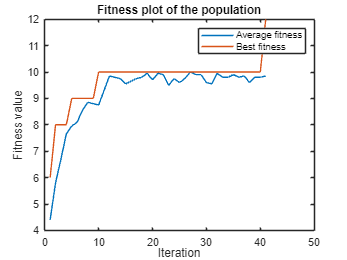


%Average fitness and Best fitness plot
%If solution is found at first iteration, count=0, plot is useless
if count > 0
    figure()
    plot(average_fitness(1:count)); %Average fitness plot
    hold on
    plot(best_fitness(1:count));
    title('Fitness plot of the population');
    legend('Average fitness', 'Best fitness');
    xlabel('Iteration');ylabel('Fitness value');
end



%Clearing unused variables
clear i; clear idx; clear max_count; clear count;

## **Convergence Results**

The genetic algorithm's convergence speed depends on the target sequence's complexity and the initialization of test sequences. 

- **Simple target sequences** with distinct, ordered values (e.g., **[1,2,3,4,5,6]**) lead to a fast convergence, as incorrect guesses are easily corrected; 

- **Complex target sequences** with repeated or close values (e.g., **[5,5,6,5,6,5]**) lead to a slow convergence, as mutations or crossovers often fail to solve ambiguities, leaving multiple suboptimal solutions with similar fitness scores.

- ** Initialization** also plays a critical role: test sequences closer to the target require fewer iterations to converge, while if the initial guesses are messy, the algorithm spends more time in a chaotic "trial and error" phase before aligning the result to the target.

## **Fitness Behaviour**

**The best fitness** score outperforms the average fitness from the first iteration as mathematically expected, improving gradually or in sudden jumps (step function) as the population refines toward the target.

 In contrast, **average fitness** exhibits more unstable swinging behaviour. In fact the algorithm first searches wildly for good options, then fine-tunes the best ones. Complex target and test structures amplify these fluctuations, as the algorithm explores diverse solutions in "trial and error" steps.

## FUNCTIONS 

## Evaluate_fitness

Computes the fitness of a population compared to a target sequence, based on the number of correct symbols in the right and wrong positions.

The fitness function is defined as: $2 N_{\text{cgpg}} + N_{\text{cgps}}$ where correct placements $N_{cgpg}$ are rewarded more heavily than correct symbols in wrong positions $N_{cgps}$.

function [Ncgpg, Ncgps, fitness_individuals]=evaluate_fitness(test, target, alphabet, fitness)

% INPUTS:
% test: population of candidate sequences made up of P individuals and Nb symbols (P x Nb)
% target: target sequence to be guessed (1 x Nb)
% alphabet: row vector of allowed symbols for the sequences
% fitness: handle function measuring the survivability of individuals wrt. the problem
%
% OUTPUT:
% Ncgpg: number of right colours in right position (scalar)
% Ncgps: number of right colours in wrong position (scalar)
% fitness_individuals: fitness value for each individual (P x 1)

%-------------------------------------------------------------------------------------------------------
%---------------------------------------------INPUT CHECK-----------------------------------------------
%-------------------------------------------------------------------------------------------------------

%Check on the number of inputs on the function
if nargin~=4
    error("The number of inputs in the function must be 4");
end

% Check on the alphabet used
if(~isrow(alphabet))
    error("The alphabet (third input) must be a row vector");
end

if ~(isnumeric(alphabet) ||  ischar(alphabet))
    error("The alphabet (third input) must be a fully numerical vector or fully character vector");
end

% Check on the test and target sequences
if(~ismatrix(test))
    error("The test (first input) must be a matrix");
end

if(~isrow(target))
    error("The target (second input) must be a row vector");
end

if(size(target,2)~=size(test,2))
    error("The columns of the test (first input) and length of the target (the second input) must match");
end

if(~all(ismember(test, alphabet)==1))
    error("The test (first input) must use symbols in alphabet (third input)");
end

if(~all(ismember(target, alphabet)==1))
    error("The target (second input) must use symbols in alphabet (third input)");
end

% Check on the fitness function
if ~isa(fitness, 'function_handle')
    error("Fitness function (fourth input) must be a valid function handle");
end

%-------------------------------------------------------------------------------------------------------
%----------------------------------------------------MAIN-----------------------------------------------
%-------------------------------------------------------------------------------------------------------

%Defining the counter Ncgpg:
%Vector P x 1 containing the number of right colours in right place for each individual
Ncgpg=sum(test-target==0, 2);

%Defining the counter Ncgps:
%Vector P x 1 containing the number of right colours in wrong place for each individual

%Vector counting frequence of each colour in the target (1 x Nb)
target_count = arrayfun(@(x) sum(target==x), alphabet);
%Vector counting frequence of each colour for each individual (P x Nb)
test_count = cell2mat(arrayfun(@(x) sum(test==x, 2), alphabet, 'UniformOutput', false));
%Vector containing the minimum component-wise (P x Nb)
minimum=min(target_count, test_count);
%Vector counting P x 1
Ncgps=sum(minimum,2);
%Excluding from the counting the right colours in right position
Ncgps=Ncgps-Ncgpg;

%Fitness computation for each individual
fitness_individuals=fitness(Ncgpg, Ncgps);
end

## Tournament_selection

Selects two parent individuals from a population using a tournament-based selection strategy. A random subset of the population (made of T individuals) is selected and the two individuals with the highest fitness in this subset are chosen as parents for reproduction.

function [parent1, parent2]=tournament_selection(test, fitness_individuals, T)

% INPUTS:
% test: population of candidate sequences made up of P individuals and Nb symbols (P x Nb)
% fitness_individuals: fitness value for each individual (P x 1)
% T: number of individuals of the population required to fight in tournament
%
% OUTPUT:
% parent1 / parent2: individuals selected from the population to be the parents for

%-------------------------------------------------------------------------------------------------------
%---------------------------------------------INPUT CHECK-----------------------------------------------
%-------------------------------------------------------------------------------------------------------

%Check on the number of inputs on the function
if nargin~=3
    error("The number of inputs in the function must be 3");
end

%Check on the test sequences and their fitness
if(~ismatrix(test))
    error("The test (first input) must be a matrix");
end

if(~iscolumn(fitness_individuals))
    error("The fitness (second input) must be a column vector");
end

if(size(test,1)~=size(fitness_individuals,1))
    error("The rows of the test (first input) and length of the fitness (the second input) must match");
end

%Check on the size of the population. For the designed tournament
%selection at least T individuals are required!

if(size(test,1)<T)
    error("The rows of the test (first input) must be more than T (third input)");
end

%Check on the number of individuals chosen from the population to fight
if(~isscalar(T) || T<=1)
    error("The number of individuals chosen (third input) must be a scalar, greater or equal to 2");
end

%-------------------------------------------------------------------------------------------------------
%----------------------------------------------------MAIN-----------------------------------------------
%-------------------------------------------------------------------------------------------------------

%Defining the number of individuals in the population
P=size(test,1);
p=randperm(P); %Permutating the individuals
%Selecting the first T individuals according to the random permutation
T_fitness=fitness_individuals(p(1:T));
%Selecting the best two fitness values for the T individuals chosen
[~, index]=maxk(T_fitness, 2);
%Genetic code of the two individuals chosen
parent1=test(p(index(1)),:);
parent2=test(p(index(2)),:);
end

## Crossover

Generates two offspring sequences from two parent sequences simulating the natural genetic reproduction in combining the genetic material of two parents. 

With probability $P_c$, the function performs one of three crossover types: 

- In **one-point crossover**, a single random cut point is selected along the parent sequences. The genetic material is exchanged after this point, producing two new offspring.

- In **two-point crossover**, two random cut points are selected. The segment between these two points is swapped between the parents to form the offspring.

- In **uniform crossover**, each gene is swapped  between the two parents with a 50% chance. 

If crossover is not performed, the children are clones of the parents.

function [child1, child2]=crossover(parent1,parent2, alphabet, Pc, crossover_type)

% INPUTS:
% parent1: first parent sequence (1 x Nb)
% parent2: second parent sequence (1 x Nb)
% alphabet: row vector of allowed symbols for the sequences
% Pc: probability of crossover (scalar in [0,1])
% crossover_type:  1 for one-point crossover
%                  2 for two-point crossover
%                  3 for uniform crossover

% OUTPUTS:
% child1/child2: offspring sequences generated from parents (1 x Nb).

%-------------------------------------------------------------------------------------------------------
%---------------------------------------------INPUT CHECK-----------------------------------------------
%-------------------------------------------------------------------------------------------------------

%Check on the number of inputs on the function
if nargin~=5
    error("The number of inputs in the function must be 5");
end

%Check on the individuals/sequences chosen for reproduction
if(~isrow(parent1) || ~isrow(parent2))
    error("The parents (first and second input) must be row vectors");
end

if(size(parent1,2)~=size(parent2,2))
    error("The length of the parents (first and second input) must match");
end

%Check on the alphabet used for the sequences
if(~isrow(alphabet))
    error("The alphabet (third input) must be a row vector");
end

if(~all(ismember(parent1, alphabet)==1))
    error("The first parent (first input) must use symbols in alphabet (third input)");
end

if(~all(ismember(parent2, alphabet)==1))
    error("The second parent (second input) must use symbols in alphabet (third input)");
end

if ~(isnumeric(alphabet) ||  ischar(alphabet))
    error("The alphabet (third input) must be a fully numerical vector or fully character vector");
end

%Check on the probabilities of crossover
if(~isscalar(Pc) || Pc<0 || Pc>1)
    error("The probability of crossover (the fourth input) must be a scalar in interval [0,1]");
end


% Check on crossover type
if ~isscalar(crossover_type) || ~ismember(crossover_type, [1, 2,3])
    error("crossover type (fifth input) must be 1 (one-point), 2 (two-point) or 3 (uniform)");
end

%-------------------------------------------------------------------------------------------------------
%----------------------------------------------MAIN CROSSOVER-------------------------------------------
%-------------------------------------------------------------------------------------------------------

Nb=size(parent1,2); %Number of symbols used in the sequences

% Initialize children as clones
child1 = parent1;
child2 = parent2;

if rand <= Pc  % Probability of performing crossover

    %ONE-POINT CROSSOVER
    if crossover_type == 1
        cut = randi(Nb - 1);
        child1(cut+1:end) = parent2(cut+1:end);
        child2(cut+1:end) = parent1(cut+1:end);

        %TWO-POINTS CROSSOVER
    elseif crossover_type == 2
        cuts = randi([1, Nb-1], 1, 2);
        cut1 = min(cuts);
        cut2 = max(cuts);
        child1(cut1+1:cut2) = parent2(cut1+1:cut2);
        child2(cut1+1:cut2) = parent1(cut1+1:cut2);

        %UNIFORM CROSSOVER
    elseif crossover_type == 3
        mask = rand(1, Nb) > 0.5;
        child1(mask) = parent2(mask);
        child2(mask) = parent1(mask);
    end
end
end

## Mutation

After crossover, each child is independently subject to mutation with probability $P_m$. It's performed by replacing randomly a gene with a new value from the alphabet, excluding the current gene value. This steps promote genetic diversity in the population.

function individual = mutation(individual, alphabet, Pm)

% INPUTS:
% individual: individual sequence (1 x Nb)
% alphabet: row vector of allowed symbols for the sequences
% Pm: probability of mutation (scalar in [0,1])

% OUTPUTS:
% individual: mutated individual sequence (1 x Nb)

%-------------------------------------------------------------------------------------------------------
%---------------------------------------------INPUT CHECK-----------------------------------------------
%-------------------------------------------------------------------------------------------------------

%Check on the number of inputs on the function
if nargin~=3
    error("The number of inputs in the function must be 3");
end

%Check on the individuals/sequences chosen for reproduction
if(~isrow(individual))
    error("The individual (first input) must be row vectors");
end

%Check on the alphabet used for the sequences
if(~isrow(alphabet))
    error("The alphabet (second input) must be a row vector");
end

if(~all(ismember(individual, alphabet)==1))
    error("The individual (first input) must use symbols in alphabet (second input)");
end

if ~(isnumeric(alphabet) ||  ischar(alphabet))
    error("The alphabet (second input) must be a fully numerical vector or fully character vector");
end

%Check on the probabilities of crossover
if(~isscalar(Pm) || Pm<0 || Pm>1)
    error("The probability of mutation (the third input) must be a scalar in interval [0,1]");
end

%-------------------------------------------------------------------------------------------------------
%----------------------------------------------MAIN MUTATION--------------------------------------------
%-------------------------------------------------------------------------------------------------------

Nb=size(individual,2); %Number of symbols used in the sequences

if rand < Pm
    mutation_position=randi(Nb); %Defining position of the mutating gene
    current_value = individual(mutation_position); %Checking the actual gene before mutation

    %Defining a new alphabet, deleting the actual gene value from the alphabet
    alphabet(alphabet== current_value) = [];

    %Selecting a new gene from the new alphabet
    %new_value = randsample(alphabet_new, 1);   %statistics and machine learning toolbox required
    new_value = alphabet(randi(length(alphabet)));
    individual(mutation_position) = new_value;
end
end
